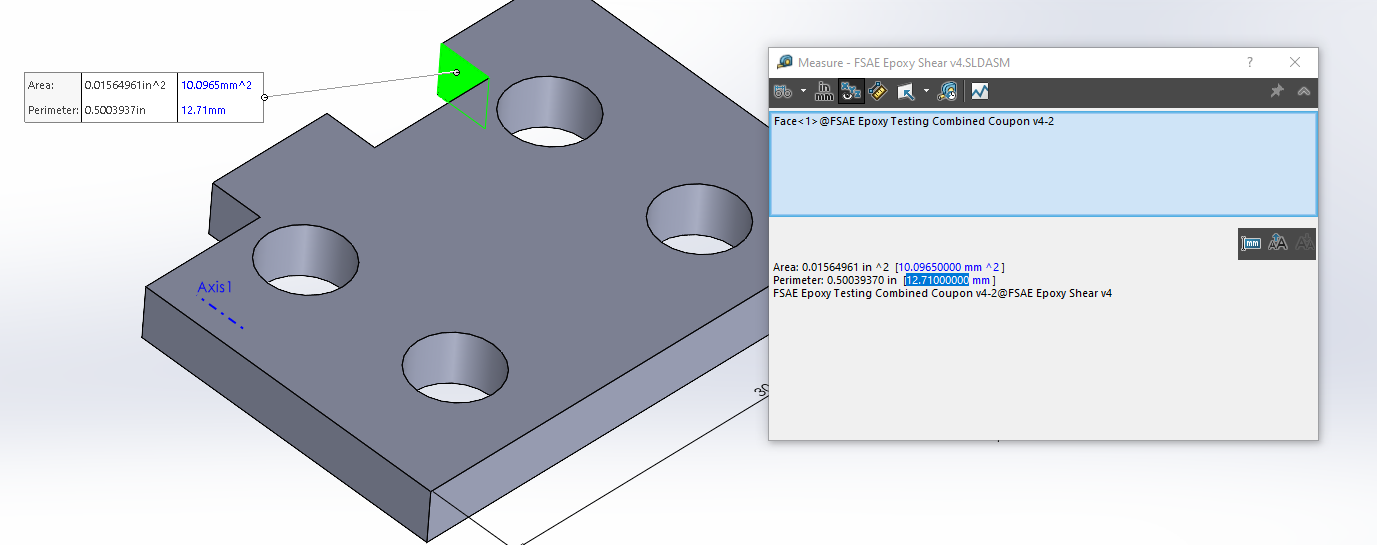

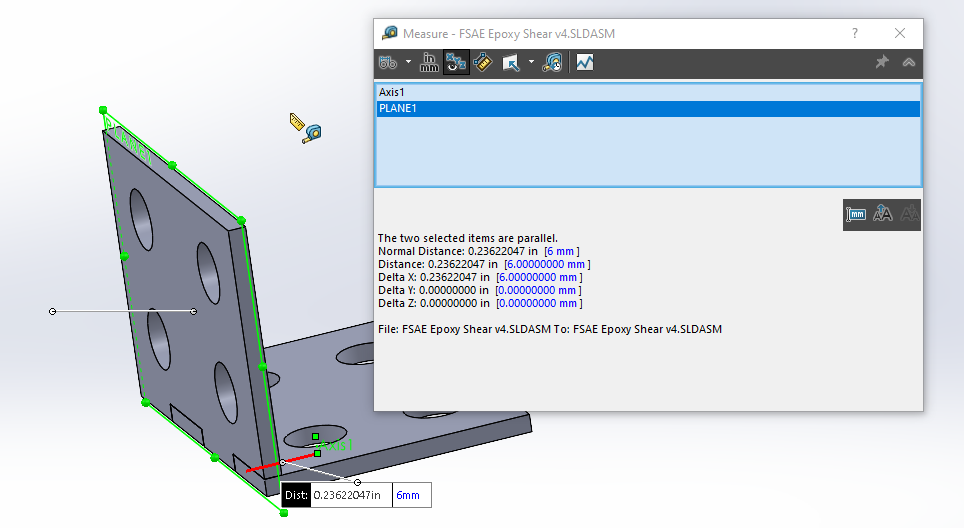

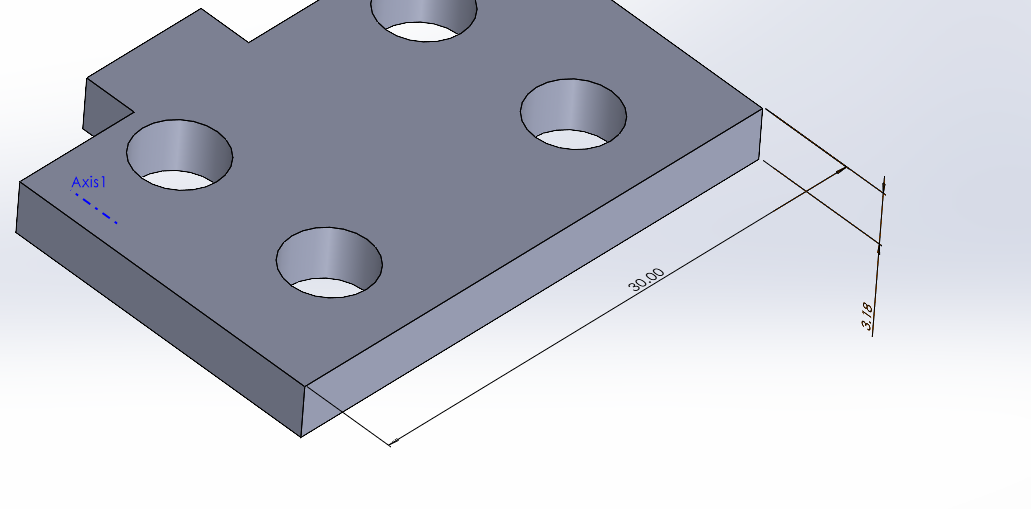

t = 3.175*.001%m 

t = 0.0032


A1 = 21.83*.001^2%m^2

A1 = 2.1830e-05

I1 = 3.85*.001^4%m^4

I1 = 3.8500e-12


A2 = A1

A2 = 2.1830e-05

I2 = I1

I2 = 3.8500e-12


A3 = 30.29*.001^2%m^4

A3 = 3.0290e-05

I3 = 50.97*.001^4%m^4

I3 = 5.0970e-11


syms M P sigma_b tau sigma_T sigma_1 sigma_2
eq1 = M == 0.006*P

$$eq1 = M=\frac{3\,P}{500}$$

b = 0.03;
h = 0.00318;
c = t/2;

tau_yp = 1100*6894.76%pa

tau_yp = 7584236


eq2 = sigma_b == (M*c)/(b*h^3/12)

$$eq2 = \sigma_{b}=\frac{4797924346595559537115136\,M}{242974686483135625}$$


A = 10.0965*.001^2;%m^2

eq3 = tau == P/A

$$eq3 = \tau =\frac{36893488147419103232\,P}{372495103080417}$$


eq4 = sigma_T == P/(b*h)

$$eq4 = \sigma_{T}=\frac{73786976294838206464\,P}{7039277538527565}$$

## Principal Stresses

eq5 = sigma_1 == (sigma_b + sigma_T)/2 + sqrt( ((sigma_b - sigma_T)/2)^2 + tau^2)

$$eq5 = \sigma_{1}=\frac{\sigma_{T}}{2}+\frac{\sigma_{b}}{2}+\sqrt{{\left(\frac{\sigma_{T}}{2}-\frac{\sigma_{b}}{2}\right)}^{2}+\tau^{2}}$$

eq6 = sigma_2 == (sigma_b + sigma_T)/2 - sqrt( ((sigma_b - sigma_T)/2)^2 + tau^2)

$$eq6 = \sigma_{2}=\frac{\sigma_{T}}{2}+\frac{\sigma_{b}}{2}-\sqrt{{\left(\frac{\sigma_{T}}{2}-\frac{\sigma_{b}}{2}\right)}^{2}+\tau^{2}}$$


eq7 = 0.5*sigma_1 == tau_yp

$$eq7 = \frac{\sigma_{1}}{2}=7584236$$


eqs = eq1,eq2,eq3,eq4,eq5,eq7;

$$eqs = M=\frac{3\,P}{500}$$

$$eq2 = \sigma_{b}=\frac{4797924346595559537115136\,M}{242974686483135625}$$

$$eq3 = \tau =\frac{36893488147419103232\,P}{372495103080417}$$

$$eq4 = \sigma_{T}=\frac{73786976294838206464\,P}{7039277538527565}$$

$$eq5 = \sigma_{1}=\frac{\sigma_{T}}{2}+\frac{\sigma_{b}}{2}+\sqrt{{\left(\frac{\sigma_{T}}{2}-\frac{\sigma_{b}}{2}\right)}^{2}+\tau^{2}}$$


solve(eq7,sigma_1)

$$ans = 15168472$$

solve(eq5,)